# Objetivo

En esta práctica utilizaremos una red neuronal para clasificar imágenes de dígitos escritos. Además, utilizaremos el filtro de Gabor y reduciremos las imágenes para detectar mejor las características.

# Prácticas anteriores, qué se necesita

- Gabor kernel Filter (gabor_kernel, gabor_reduce, gabor_template)

- Reduce Image (reduce_image)

- MLP con las funciones necesarias (GetError_class.m, sigmoid.m, sigmoidGradient.m, learningNN_class.m, gradientNN_class.m) u los parámetros (iteraciones, número de neuronas en la capa oculta, alpha)

General schema:

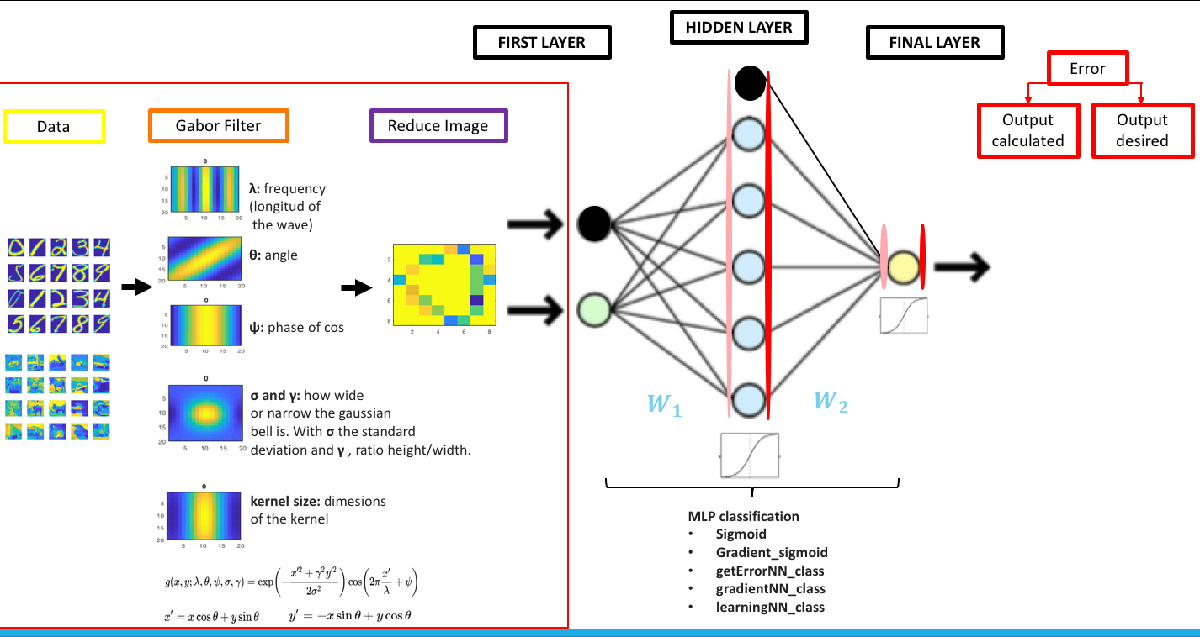

clear all

%% Elige 2 dígitos entre 0 y 9:
num1 = ;
num2 = ;

% NO modificar (esta función separa trainset, data, y testset, data_val) para los 2 dígitos elegidos
[data,data_val,Ytrain,Yval] = GetData(num1,num2);

% data: datos del conjunto de entrenamiento
% data_val: datos del conjunto de validación
% Ytrain: etiquetas del conjunto de datos de entrenamiento
% Yval: etiquetas del conjunto de datos de validación


%% Elegir los parámetros de los filtros de Gabor
kern_size = ;  % Kernel size
lambda = ;     % wavelength (1/frequency)
phi = ;        % phase offset
sigma = ;      % Gaussian dispersion
gamma = ;    % height / amplitude ratio

% NO modificar:
fig = false;
orientations = [0,pi/4, pi/2, 3*pi/4]; %filter orientations
image_size = [16 16]; %size of the original images
reduction_factor = 2; 

% Convolución de los datos de entrenamiento:
Xtrain = gabor_reduce(data, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,true);
% Convolución de los datos de validación:
Xval = gabor_reduce(data_val, reduction_factor, orientations, kern_size, lambda, phi, sigma, gamma, image_size,false);

En esta práctica necesitaremos más neuronas en la capa de entrada que en la práctica 3. Asegúrate de que gradientNN_class.m tiene en cuenta esto (W1_grad = d_h*x';).

%%  MLP

% Elige los parámetros de la red neuronal:
hidden_units = ;
max_iter = ;
alpha = ;

% Gradient Descent: llama a la función de aprendizaje


Como en la práctica 3, a continuación evaluamos el clasificador viendo cuántos patrones se clasifican correctamente. La variable **pred** (predicción) valdrá 0 ó 1 dependiendo de si la clase predicha es 1 ó 2. Para ello fijamos los valores de **y** que son iguales a 0 por debajo de 0,5 y los de 1 por encima de 0,5.

%% Predecir la clasificación con datos de entrenamiento
numpatt = size(Xtrain,2);
y = zeros(numpatt,1);
for p = 1:numpatt  % pattern loop       
    x = Xtrain(:,p); % muestra de entrada p
    % calcula la activación para las neuronas de la capa oculta:
    z_h = ;  % suma antes de la sigmoide
    a_h = ;  % activación de las neuronas de la capa oculta
    a_h = ;  % añade el término de sesgo
    
    % Calcula la activación para la neurona de salida
    z_out = ;  % suma antes de la respuesta de la neurona de salida
    y(p) = ;  % calcula la respuesta de la neurona de salida (regression: identity - classification: logistic sigmoid)
end   

pred_t = ;
correct = ;
display(['' ])


class1 = ;
class2 = ;
cor_class1 = ;
cor_class2 = ;

%% Predecir la clasificación con los datos de validación
numpattval = size(Xval,2);
yval = zeros(numpattval,1);
for p = 1:numpattval  % pattern loop       
    x = Xval(:,p); % entrada de muestra p
    % calcula la activación para las neuronas de la capa oculta:
    z_h = ;  % suma antes de la sigmoide
    a_h = ;  % activación de las neuronas de la capa oculta
    a_h = ;  % añade el término de sesgo

    % Calcula la activación para la neurona de salida
    z_out = ;  % suma antes de la respuesta de la neurona de salida
    yval(p) = ;  % calcula la respuesta de la neurona de salida (regression: identity - classification: logistic sigmoid)
end   


pred_val = ;
correct = ;
display(['' ])

class1_val = ;
class2_val = ;
cor_class1_val = ;
cor_class2_val = ;


Visualización de la precisión del MLP para clasificar los datos de entrenamiento y validación:

%Gráficas de error y predicciones
figure('NumberTitle', 'off', 'Name', 'Error and Predictions');
set(gcf,'units','normalized','position',[0,0.25,1,0.4])

subplot(121),cla
plot(, 'color', [.9 .4 0], 'linewidth', 2), hold on
plot(, '--','color', [.0 .7 .2], 'linewidth', 1)
xlabel('iteraciones', 'fontsize', 14)
ylabel('error', 'fontsize', 14)
legend({'training error', 'validation error'}, 'fontsize', 14)
set(gca, 'fontsize', 14,'yscale','log','xscale','log'), grid on

subplot(122),cla
bar(1, ,'facecolor', [.8 .1 .1])
hold on
bar(2, ,'facecolor', [.15 .2 .7])
bar(3, ,'facecolor', [.8 .1 .1])
bar(4, , 'facecolor', [.15 .2 .7])
ylabel('Porcentaje de aciertos', 'fontsize', 14), ylim([0, 1.05])
legend(num2str(num1),num2str(num2),'location','bestoutside'),xlim([0 5])
set(gca, 'fontsize', 14, 'XTick', [1.5,3.5],'XTickLabel',{['training'], 'validacion'} )

%Plot Predicciones
figure('NumberTitle', 'off', 'Name', 'Training Predictions');
for i = 1:size(pred_t,1)
   ax1 = subplot(21,10,i);
   img = reshape(data(i,:), image_size)';
   imagesc(img);
   axis off
   if pred_t(i) == 1
      colormap(ax1, summer)
   end
   if pred_t(i) == 0
      colormap(ax1, winter)
   end
   if pred_t(i) ~= Ytrain(i)
      colormap(ax1, spring)
   end
end
ax1 = subplot(21,10,202);
imagesc(zeros(16,16));
colormap(ax1, summer)
axis off
text(7 ,25, num2str(num1))
ax1 = subplot(21,10,205);
imagesc(zeros(16,16));
colormap(ax1, winter)
axis off
text(7 ,25, num2str(num2))
ax1 = subplot(21,10,208);
imagesc(zeros(16,16));
colormap(ax1, spring)
axis off
text(-5 ,25, 'Misslabeled!')

figure('NumberTitle', 'off', 'Name', 'Validation Predictions');
for i = 1:size(pred_val,1)
   ax1 = subplot(21,10,i);
   img = reshape(data_val(i,:), image_size)';
   imagesc(img);
   axis off
   if pred_val(i) == 1
      colormap(ax1, summer)
   end
   if pred_val(i) == 0
      colormap(ax1, winter)
   end
   if pred_val(i) ~= Yval(i)
      colormap(ax1, spring)
   end
end
ax1 = subplot(21,10,202);
imagesc(zeros(16,16));
colormap(ax1, summer)
axis off
text(7 ,25, num2str(num1))
ax1 = subplot(21,10,205);
imagesc(zeros(16,16));
colormap(ax1, winter)
axis off
text(7 ,25, num2str(num2))
ax1 = subplot(21,10,208);
imagesc(zeros(16,16));
colormap(ax1, spring)
axis off
text(-5 ,25, 'Misslabeled!')